age = [3:1:9 11 12 14 15 16 17]

age =      3     4     5     6     7     8     9    11    12    14    15    16    17


wing_length = [1.4 1.5 2.2 2.4 3.1 3.2 3.2 3.9 4.1 4.7 4.5 5.2 5.0]

wing_length =     1.4000    1.5000    2.2000    2.4000    3.1000    3.2000    3.2000    3.9000    4.1000    4.7000    4.5000    5.2000    5.0000



disp("1. relationship between age and wing length")

1. relationship between age and wing length


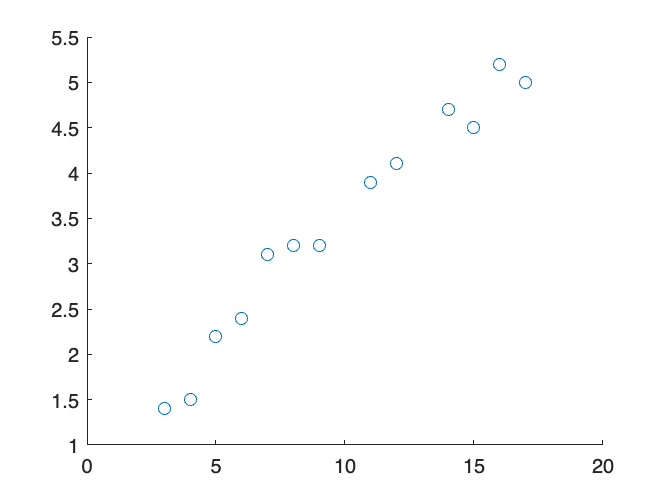

scatter(age, wing_length)

%2-4. calc and plot regression line 
regression = fitlm(age, wing_length, "linear")

regression = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate       SE       tStat       pValue  
                   ________    ________    ______    __________

    (Intercept)    0.82962      0.16774    4.9459    0.00043849
    x1             0.26468     0.015559    17.012    3.0097e-09


Number of observations: 13, Error degrees of freedom: 11
Root Mean Squared Error: 0.256
R-squared: 0.963,  Adjusted R-Squared: 0.96
F-statistic vs. constant model: 289, p-value = 3.01e-09

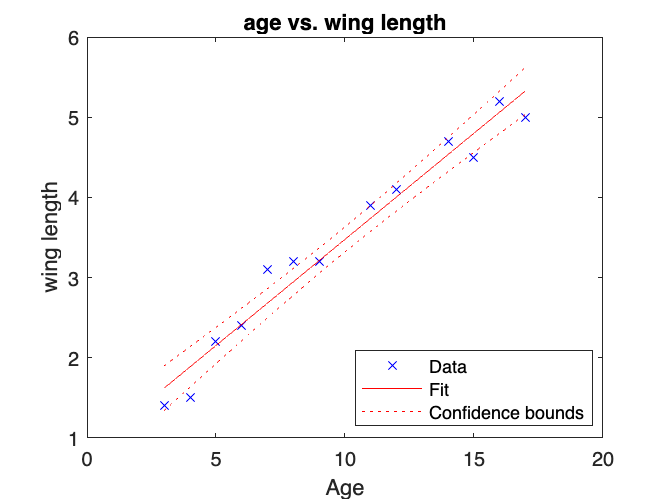

plot(regression)
title("age vs. wing length")
xlabel("Age")
ylabel("wing length")


%3. yes, we can reject H null. 

r = corrcoef(age,wing_length)

r =     1.0000    0.9815
    0.9815    1.0000


r2 = r(2,1).^2

r2 = 0.9634



%not sure how to add noise

disp("confidence intervals")

confidence intervals


coefCI(regression)

ans =     0.4604    1.1988
    0.2304    0.2989
